% Total 3d calibration for 2 color
% here we're assuming the calibration stack repeats between orange-red-step
% in that order
clearvars;
close all
clc
%% User variables
pixw = 6;                                                                   % ROI 'radius'
q = 0.120;                                                                  % Pixel size in um
step = 50;                                                                  % Steps between frames in nm
CCs = 10;                                                                   % number of frames to x-correlate over
wind = -pixw:pixw;                                                          % create window for segmentation
check_psfs = 1;
%% File loading and image segmentation
files = dir('*tif');
% Counting variable for populating psfs
colors = {'orange','red'};                                                  % Variable to flip between color structures
channel_split = 200; % split between spectral channels, determined empirically by looking at data


## Point Spread Function Segmentation

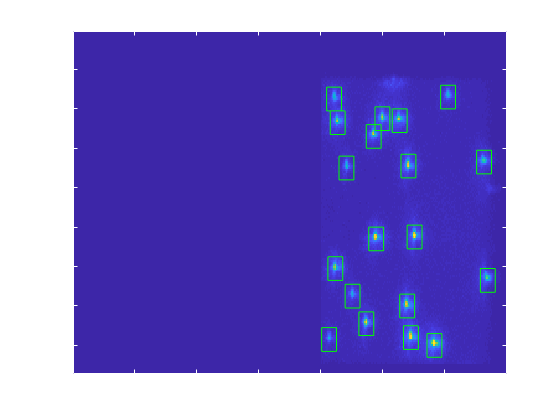

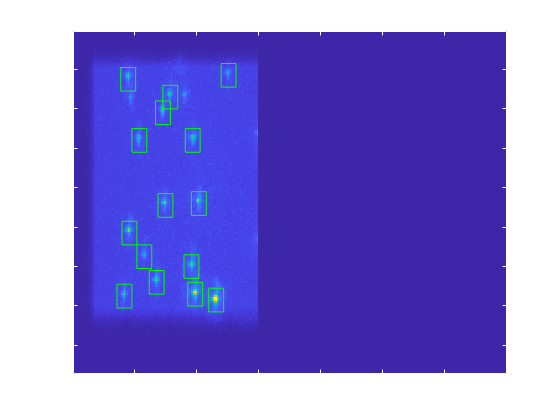

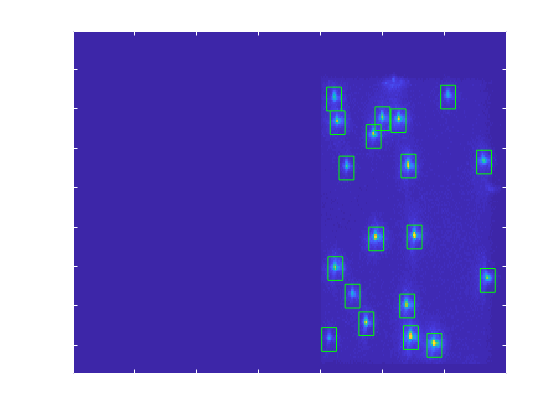

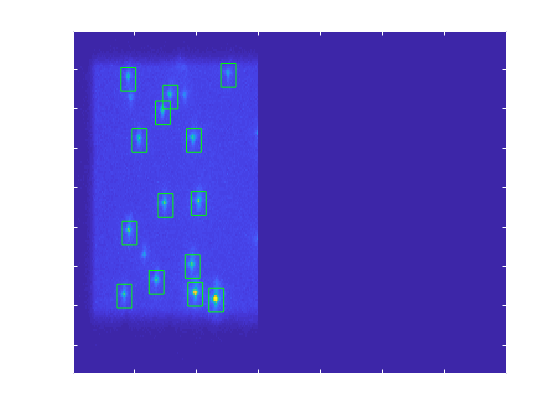

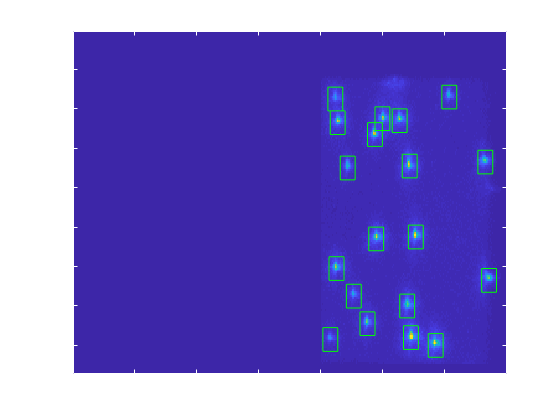

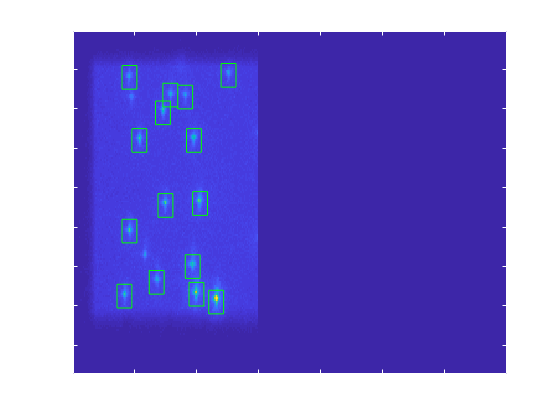

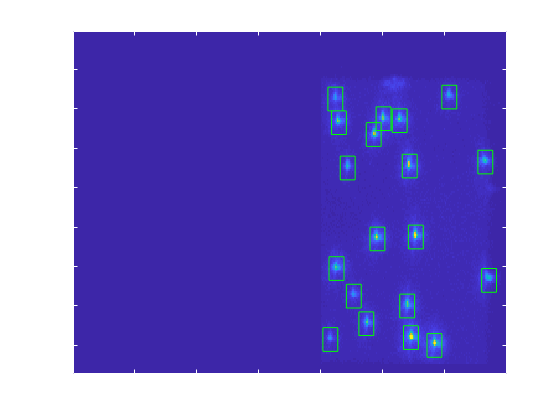

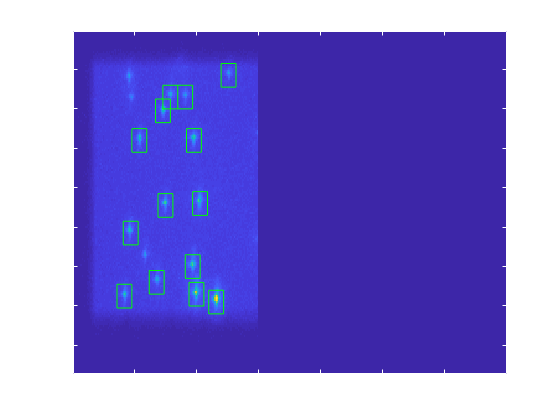

% Segment out PSFs
pind.orange = 1;                                                                   % Counting variable for populating psfs
pind.red = 1;
for i = 1:numel(files)                                                     % Loop over all files
    raw_images = gpu_rball(readtiff(files(i).name));                        % Load file and background subtract
    for jj = 1:2 % Cycle through colors
        %         if pind.(colors{jj}) == 26
        %             waitforbuttonpress;
        %
        %         end
        if i == 14
            images(i).(colors{jj}) = raw_images(:,:,(3-jj):2:end);    
        else
            images(i).(colors{jj}) = raw_images(:,:,(jj):2:end);
        end
        
        if jj == 2
            images(i).(colors{jj})(:,1:4,:) = 0;
            images(i).(colors{jj})(end-4:end,:,:) = 0;
            images(i).(colors{jj})(:,end-channel_split:end,:) = 0;
            images(i).(colors{jj})(1:4,:,:) = 0;
        else
            images(i).(colors{jj})(:,1:channel_split,:) = 0;
            images(i).(colors{jj})(end-4:end,:,:) = 0;
            images(i).(colors{jj})(:,end-4:end,:) = 0;
            images(i).(colors{jj})(1:4,:,:) = 0;
        end
        
        if check_psfs == 1 % Check the algorithm is properly collecting point spread functions
            figure
            imagesc(max(images(i).(colors{jj}),[],3))                                              % Represent maximal image
            title(['File ', num2str(i), ' ', colors{jj},' channel'])
        end
        psf = denoise_psf(max(images(i).(colors{jj}),[],3),2);                                    % use wavelet transform to identify molecules
        dps = das_peaks(psf,20);                                                % Peak finder
        [row,col] = find(dps == 1);                                             % Find peaks in dps
        for j = 1:numel(row)                                                    % loop over all locations, but attempt to center the maximum pixel on each sub image
            if check_psfs == 1
                draw_boxes([col,row],pixw);                                         % Show location of found regions on representation
            end
            try
                for k = 1:numel(images(i).(colors{jj})(1,1,:))
                    [m,n,o] = size(images(i).(colors{jj}));
                    if row(j)-pixw > 0 && row(j)+ pixw < m && col(j)-pixw > 0 && col(j)+ pixw < n
                        [r,c] = find(images(i).(colors{jj})(row(j) + wind, col(j) + wind,k) == max(max(images(i).(colors{jj})(row(j) + wind, col(j) + wind,k)))); % find maxima pixel in subregion
                        psf_off.(colors{jj}){pind.(colors{jj})}(k,:) = [c(1),r(1)];
                        psfs.(colors{jj}){pind.(colors{jj})}(:,:,k) = images(i).(colors{jj})((row(j) - pixw - 1) + r(1) + wind, col(j) - pixw - 1 + c(1) + wind,k); % Store psfs in their own variable
                        file_frame.(colors{jj})(pind.(colors{jj})) = i;
                    end
                end
                if ~isempty(psfs.(colors{jj}){pind.(colors{jj})})
                    pind.(colors{jj}) = pind.(colors{jj}) +1;
                end
                
            catch lsterr
                %                 waitforbuttonpress
            end
        end
    end
end

% Memory Management
% At this point all regions of interest are saved in psfs
clear raw_images dps psf row col files images pind

## Elipticity Analysis

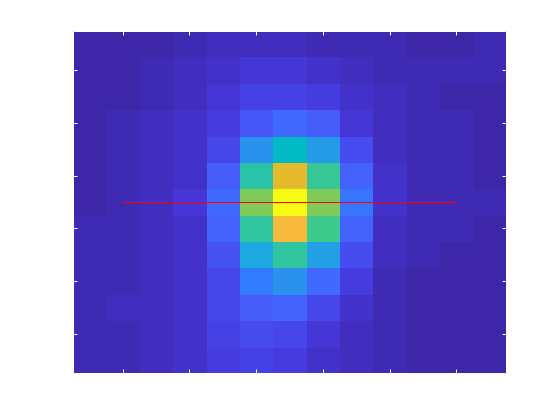

The measured angle of elipticity for the orange channel was 0 +/- 0.0064632 radians


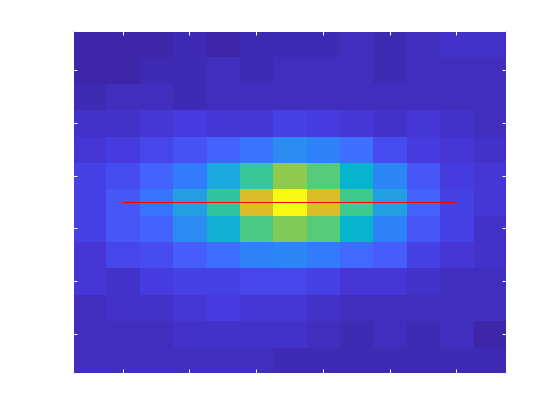

The measured angle of elipticity for the red channel was 0 +/- 0.14066 radians


% Determining angle of elipticity
frame_for_elipse = 10;
for jj = 1:2 % loop over color
    [m,n,o] = size(psfs.(colors{jj}){1});                                                    % Grab size of PSF regions
    number_of_psfs = numel(psfs.(colors{jj}));
    ang = [];
    psf = psfs.(colors{jj}){1}(:,:,1)*0;
    for i = 1:number_of_psfs      % Perform eliptical Angle determination over several frames
        try
            [a] = get_elip_ang(psfs.(colors{jj}){i}(:,:,round(o/2) - frame_for_elipse),2.5,1.5);                             % Find optimal eliptical angle
            psf = psf + psfs.(colors{jj}){i}(:,:,round(o/2) - frame_for_elipse);
            ang = [ang;a];                                                          % Save result to an array
        catch lsterr
        end
    end
    angle = mean(ang);
    angle = 0;
    cal.(colors{jj}).ang = angle;
    figure
    imagesc(psf)
    hold on
    x = 2:12;
    y = atan(angle)*(x-7) + 7;
    
    
    plot(x,y,'r')
    hold off
    disp(['The measured angle of elipticity for the ', colors{jj}, ' channel was ', num2str(angle),  ' +/- ', num2str(std(ang)/i^0.5), ' radians'])
end

clear psf

## Fitting Analysis

for jj = 1:2
    % Preallocate fitting variables
    xf.(colors{jj})       = [];
    yf.(colors{jj})       = [];
    N.(colors{jj})        = [];
    sx.(colors{jj})       = [];
    sy.(colors{jj})       = [];
    O.(colors{jj})        = [];
    xfc.(colors{jj})      = [];
    yfx.(colors{jj})      = [];
    Oc.(colors{jj})       = [];
    Nc.(colors{jj})       = [];
    sxc.(colors{jj})      = [];
    syc.(colors{jj})      = [];
    yfc.(colors{jj})      = [];
    llv.(colors{jj})      = [];
    fnum.(colors{jj})     = [];
    psf.(colors{jj})      = [];
    ims.(colors{jj})      = [];
    psf_file.(colors{jj}) = [];
    % gpu fit of PSFs
    % NOTE TO USER: because we assume an axis of elipticity that
    % need not be parallel to the axis of the camera we rotate our
    % grid to perform the fit. This rotation is corrected for on
    % the back end and the X-Y positions returned are understood to
    % be on the axis of the camera. However, the sigma values exist
    % along the rotated or prime axis. This is representated in the
    % following comments once and is to be understood that
    % Sigma-x/y corresponds to the prime axis and not the camera
    % axis
%     if jj == 1
%         fms = 1:2:o; % input framenum
%         fms = (fms + 1) /2;
%     else
%         fms = (2:2:o)/2;
%     end
    fms = 1:o;
    
    for i = 1:numel(psfs.(colors{jj}))          % Loop over all identified ROIs
        if i ~= 1000 && i ~= 6000 && ~isempty(psfs.(colors{jj}){i})
            [fits, crlb, lv,fnout,im0s] = slim_locs(psfs.(colors{jj}){i},fms,zeros(o,2),cal.(colors{jj}).ang,50,100);  % Perform Fit
            fnout = fnout.';                                                        % Save frame number which corresponds to Z-position
            xa = fits(:,1)+psf_off.(colors{jj}){i}(fnout,1);                                     % define 'assignment' variable for x
            ya = fits(:,2)+psf_off.(colors{jj}){i}(fnout,2);                                     % define 'assignment' variable for y this allows centering around distribution
            xf.(colors{jj}) = [xf.(colors{jj});xa-mean(xa)];                                                    % X-Position
            yf.(colors{jj}) = [yf.(colors{jj});ya-mean(ya)];                                                    % Y-Position
            N.(colors{jj}) = [N.(colors{jj}); fits(:,3)];                                                     % Number of Photons
            sx.(colors{jj}) = [sx.(colors{jj});fits(:,4)];                                                    % Sigma in x' direction
            sy.(colors{jj}) = [sy.(colors{jj});fits(:,5)];                                                    % Sigma in y' direction
            O.(colors{jj}) = [O.(colors{jj}); fits(:,6)];                                                     % Offset
            % Lower bound on Variance of fitted variables
            xfc.(colors{jj}) = [xfc.(colors{jj});crlb(:,1)];
            yfc.(colors{jj}) = [yfc.(colors{jj});crlb(:,2)];
            Nc.(colors{jj}) = [Nc.(colors{jj});crlb(:,3)];
            Oc.(colors{jj}) = [Oc.(colors{jj});crlb(:,6)];
            sxc.(colors{jj}) = [sxc.(colors{jj});crlb(:,4)];
            syc.(colors{jj}) = [syc.(colors{jj});crlb(:,5)];
            psf.(colors{jj}) = [psf.(colors{jj}); fits(:,1)*i./fits(:,1)];                                            % Log the PSF the fit is associated with
            psf_file.(colors{jj}) = [psf_file.(colors{jj}); fits(:,1)*file_frame.(colors{jj})(i)./fits(:,1)];                                            % Log the PSF the fit is associated with
            llv.(colors{jj}) = [llv.(colors{jj});-abs(lv)];                                                   % Log Likelihood Value
            ims.(colors{jj}) = [ims.(colors{jj}),im0s];
            fnum.(colors{jj}) = [fnum.(colors{jj});fnout(:)];
        end
    end
    z1.(colors{jj}) = fnum.(colors{jj})*step/1000;
end

## Scan Correlation

for jj = 1:2
    %% Tolerance all sigma widths below 5 pixels
    indy = sx.(colors{jj}) < 5 & sx.(colors{jj}) >0 & sy.(colors{jj}) < 5 & sy.(colors{jj}) > 0;
    % Tolerance for pixel uncertainty
    indy = indy & sxc.(colors{jj}).^0.5*q < 30 & syc.(colors{jj}).^0.5*q < 30;
    
    refp = mode(psf.(colors{jj})(indy)); % find psf scan w/ the most number of passed fits, this is our reference psf
    rid = round(psf.(colors{jj})) == round(refp); % build an index for the reference ID
    sigr = [fnum.(colors{jj})(rid),sx.(colors{jj})(rid),sy.(colors{jj})(rid)]; % build reference sigma scan
    fnumc.(colors{jj}) = fnum.(colors{jj});
    for i = 1:numel(psfs.(colors{jj})) % loop over all psfs
        cid = psf.(colors{jj}) == i; % grab Id for psf scan to correct
        if ~isempty(psfs.(colors{jj}){i}) && sum(indy & cid) > 0
            sigc = [fnum.(colors{jj})(indy&cid),sx.(colors{jj})(indy & cid),sy.(colors{jj})(indy & cid)];
            dff(i) = xcorrsig(sigr,sigc);
            if abs(dff(i)) < 100 % If displacement is within a 'range', keep for further analysis
                fnumc.(colors{jj})(cid) = fnumc.(colors{jj})(cid) + dff(i);
                z_offset.(colors{jj})(i) = dff(i); % variable for NN placement later
            else % otherwise fully remove from analysis
                fnumc.(colors{jj})(cid) = [];
                xf.(colors{jj})(cid) = [];                                                    % X-Position
                yf.(colors{jj})(cid) = [];
                indy(cid) = [];                                    % Y-Position
                N.(colors{jj})(cid) = [];
                sx.(colors{jj})(cid) = [];
                sy.(colors{jj})(cid) = [];
                O.(colors{jj})(cid) = [];
                xfc.(colors{jj})(cid) = [];
                yfc.(colors{jj})(cid) = [];
                Nc.(colors{jj})(cid) = [];
                Oc.(colors{jj})(cid) = [];
                sxc.(colors{jj})(cid) = [];
                syc.(colors{jj})(cid) = [];
                psf.(colors{jj})(cid) = [];
                llv.(colors{jj})(cid) = [];
                ims.(colors{jj})(cid) = [];
                fnum.(colors{jj})(cid) = [];
                z1.(colors{jj})(cid) = [];
            end
        else % otherwise fully remove from analysis
            fnumc.(colors{jj})(cid) = [];
            xf.(colors{jj})(cid) = [];                                                    % X-Position
            yf.(colors{jj})(cid) = [];
            indy(cid) = [];                                    % Y-Position
            N.(colors{jj})(cid) = [];
            sx.(colors{jj})(cid) = [];
            sy.(colors{jj})(cid) = [];
            O.(colors{jj})(cid) = [];
            xfc.(colors{jj})(cid) = [];
            yfc.(colors{jj})(cid) = [];
            Nc.(colors{jj})(cid) = [];
            Oc.(colors{jj})(cid) = [];
            sxc.(colors{jj})(cid) = [];
            syc.(colors{jj})(cid) = [];
            psf.(colors{jj})(cid) = [];
            llv.(colors{jj})(cid) = [];
            ims.(colors{jj})(cid) = [];
            fnum.(colors{jj})(cid) = [];
            z1.(colors{jj})(cid) = [];
        end
    end
    z0.(colors{jj}) = fnumc.(colors{jj})*step/1000;
end

## Visualization

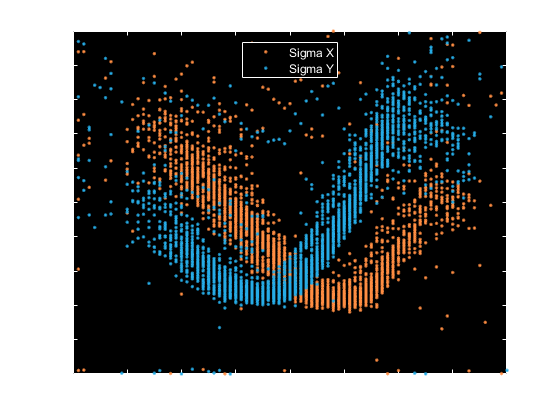

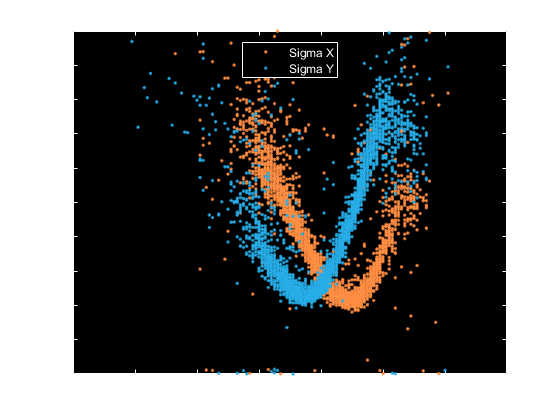

% Visualize the results up to this point

jj = 2; % 1 = orange, 2 = red
make_graphs = 1;
if make_graphs == 1
    figure
    plot(z1.(colors{jj}),sx.(colors{jj}),'.');
    hold on
    plot(z1.(colors{jj}),sy.(colors{jj}),'.');
    ylim([0,5])
%     xlim([-1,3]);
    hold off
    legend('Sigma X', 'Sigma Y','Location','North');
    xlabel('Height (um)');
    ylabel('Width (pix)');
    title([colors{jj}, ' without height adjustment'])
    
    figure
%     scatter(z0.(colors{jj}),sx.(colors{jj}),8,psf.(colors{jj}),'filled');
%     hold on
%     scatter(z0.(colors{jj}),sy.(colors{jj}),8,psf.(colors{jj}),'filled');
    plot(z0.(colors{jj}),sx.(colors{jj}),'.');
    hold on
    plot(z0.(colors{jj}),sy.(colors{jj}),'.');
    ylim([0,5])
%     xlim([-1,3]);
    hold off
    legend('Sigma X', 'Sigma Y','Location','North');
    title([colors{jj}, ' with height adjustment'])
    xlabel('Height (um)');
    ylabel('Width (pix)');
end

jj = 1

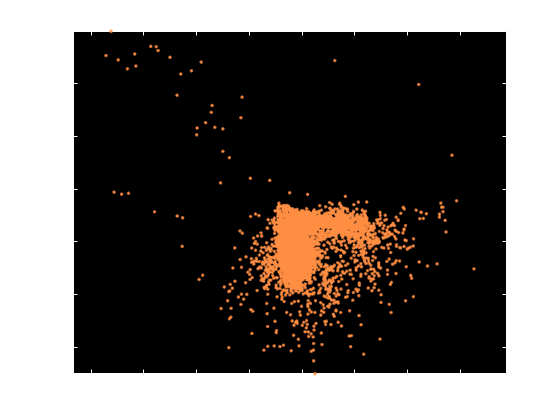

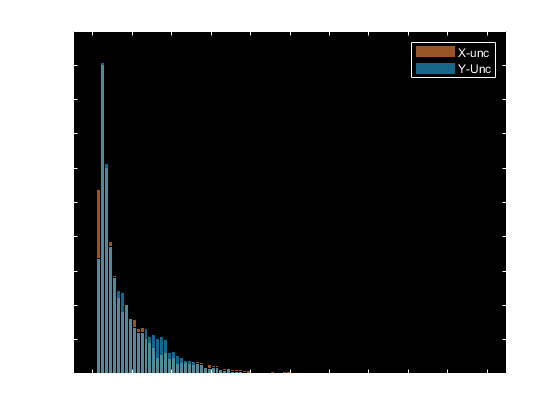


if make_graphs == 1
    % Display X-Y Position
    
    jj = 1
    figure
    indy = sxc.(colors{jj}).^0.5*q < 3 & syc.(colors{jj}).^0.5*q < 3;
    plot(xf.(colors{jj})(indy),yf.(colors{jj})(indy),'.');
    axis equal
    xlabel('X-Fit')
    ylabel('Y-Fit');
    
    
    figure
    % Display Uncertainties in Sigma Values
    
    histogram(sxc.(colors{jj})(indy).^0.5*q*1000,0:1:100,'Normalization','Probability');
    hold on
    histogram(syc.(colors{jj})(indy).^0.5*q*1000,0:1:100,'Normalization','Probability');
    legend('X-unc','Y-Unc');
    title([colors{jj}, ' sigma uncertainties'])
    xlabel('Uncertainty in um')
    ylabel('Probability');
end

## Z-Calibration

jj = 2

jj = 2

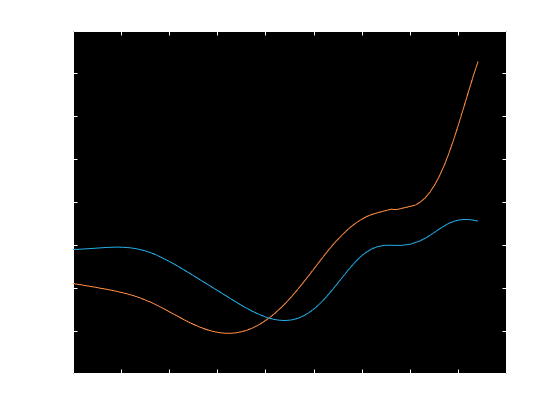

for jj = 1:2
    % select subset of data that passed tolerances for sx/sy fitting
    indy = sxc.(colors{jj}).^0.5*q < 3 & syc.(colors{jj}).^0.5*q < 3;
    sxs.(colors{jj}) = sx.(colors{jj})(indy);                                                             % Sigma X
    sys.(colors{jj}) = sy.(colors{jj})(indy);                                                             % Sigma Y
    z0s.(colors{jj}) = z0.(colors{jj})(indy);                                                             % Z-values
    zus.(colors{jj}) = unique(z0s.(colors{jj}));                                                          % Create a Unique list of Z-positions for indexing purposes
    for i = 1:numel(zus.(colors{jj}))                                                        % Loop over unique Z-Positions
        ind = z0s.(colors{jj}) == zus.(colors{jj})(i);                                                    % select the fits corresponding to a particular Z-Position
        number_of_pts(i) = sum(ind);
        subsx.(colors{jj}) = sxs.(colors{jj})(ind);                                                       % Create subset of Sigma-x corresponding to this Z-pos
        subsy.(colors{jj}) = sys.(colors{jj})(ind);                                                       % Create subset of Sigma-y corresponding to this Z-pos
        msx.(colors{jj}) = mean(subsx.(colors{jj}));                                                      % Determine Average Value of Sigma-x at this Z-pos
        stx.(colors{jj}) = std(subsx.(colors{jj}));                                                       % Determine standard deviation of Sigma-x at this Z-pos
        msy.(colors{jj}) = mean(subsy.(colors{jj}));                                                      % Determine Average Value of Sigma-y at this Z-pos
        sty.(colors{jj}) = std(subsy.(colors{jj}));                                                       % Determine standard deviation of Sigma-x at this Z-pos
        ssx.(colors{jj})(i) = mean(subsx.(colors{jj})(subsx.(colors{jj}) >= msx.(colors{jj}) - 2* stx.(colors{jj}) & subsx.(colors{jj}) <= msx.(colors{jj}) + 2* stx.(colors{jj})));      % Select only values within 2 standard deviations of the average for X'
        ssy.(colors{jj})(i) = mean(subsy.(colors{jj})(subsy.(colors{jj}) >= msy.(colors{jj}) - 2* sty.(colors{jj}) & subsy.(colors{jj}) <= msy.(colors{jj}) + 2* sty.(colors{jj})));      % Select only values within 2 standard deviations of the average for Y'
        
    end
    if jj == 1
        figure

        % for jj = 2
        plot(zus.(colors{jj}),gausssmooth(ssx.(colors{jj})-0.2,5,10))
        hold on
% %         title([colors{jj},' channel Average sigma curves'])
%         
        plot(zus.(colors{jj}),gausssmooth(ssy.(colors{jj})-0.2,5,10))
%         
        hold off
    end
end

ind = 12

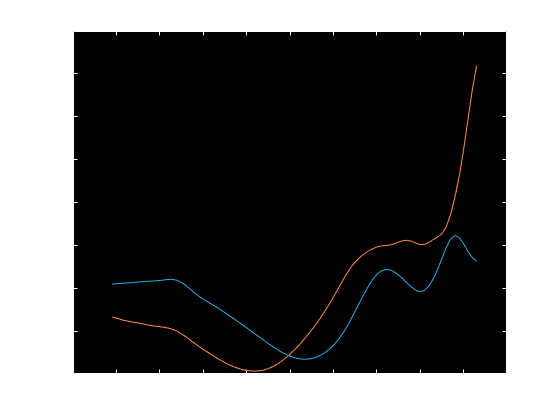

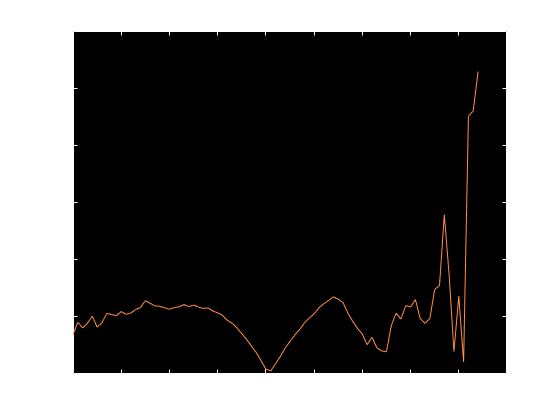

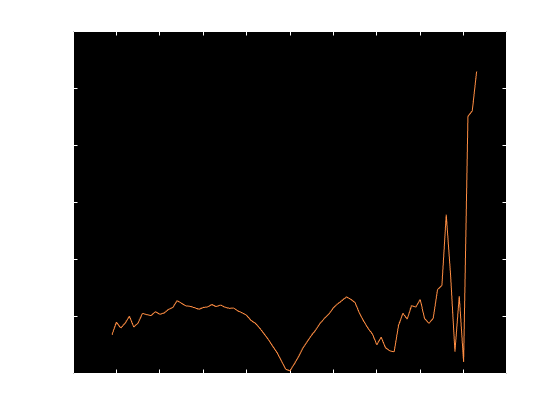

ind = 12

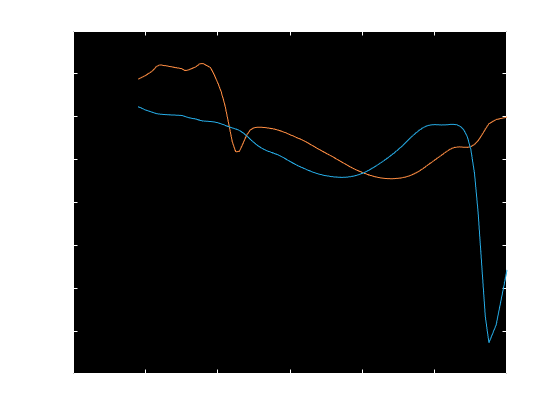

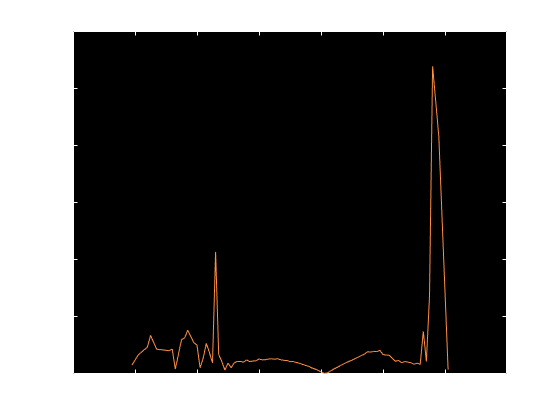

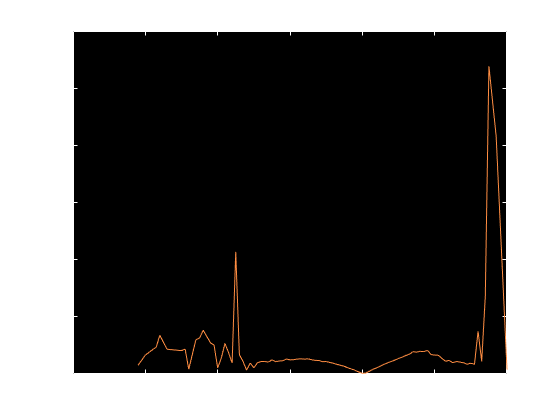

% Choosing proper separations
for jj = 1:2
    ds = ssx.(colors{jj}) - ssy.(colors{jj});                                                             % Subtract sigma-y from sigma-x
    
    bounds.(colors{jj}) = [1.5, 2.5]; % Look at the graphs below and choose a proper interval to find the minimum
    lower_bound = find(abs(zus.(colors{jj}) - bounds.(colors{jj})(1)) == min(abs(zus.(colors{jj}) - bounds.(colors{jj})(1))));
    upper_bound = find(abs(zus.(colors{jj}) - bounds.(colors{jj})(2)) == min(abs(zus.(colors{jj}) - bounds.(colors{jj})(2))));
    ind = find(abs(ds(lower_bound:upper_bound)) == min(abs(ds(lower_bound:upper_bound))))
    equal_sigma_offset.(colors{jj})= zus.(colors{jj})(ind(1) + lower_bound-1);
    z0s.(colors{jj}) = zus.(colors{jj}) - equal_sigma_offset.(colors{jj});
    smooth_sx = gausssmooth(ssx.(colors{jj}),2,10);                                                            % Plot average sigma-x
    smooth_sy = gausssmooth(ssy.(colors{jj}),2,10);
    figure
    if make_graphs == 1
        plot(z0s.(colors{jj}),smooth_sx)
        hold on
        plot(z0s.(colors{jj}),smooth_sy)
        title([colors{jj}, ' channel smoothed curve']);
        hold off
    end
    if make_graphs == 1
        figure
        plot(zus.(colors{jj}),abs(ds))
        figure
        plot(z0s.(colors{jj}), abs(ds))
    end
end

Of the values entered, 4.6154% were rejected


zf_um = struct with fields:
    orange: [6435×1 double]


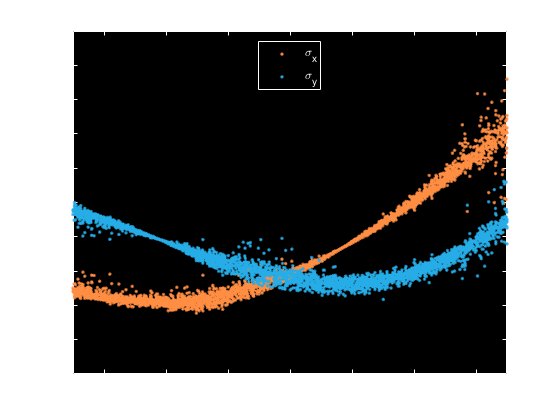

Of the values entered, 5.5556% were rejected


zf_um = struct with fields:
    orange: [6435×1 double]
       red: [3420×1 double]


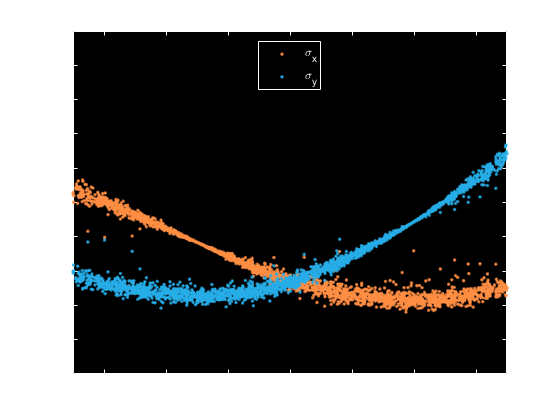

%% Building z curves
for jj = 1:2
    ind = abs(z0s.(colors{jj})) < 0.7; % choose from graphs below
    smooth_sx = gausssmooth(ssx.(colors{jj}),2,10);                                                            % Plot average sigma-x
    smooth_sy = gausssmooth(ssy.(colors{jj}),2,10);
    cal.(colors{jj}).sx = smooth_sx;
    cal.(colors{jj}).sy = smooth_sy;
    cal.(colors{jj}).z0s = z0s.(colors{jj});
    zf_um.(colors{jj}) = get_spline_z(sx.(colors{jj}),sy.(colors{jj}),cal.(colors{jj}))
    if make_graphs == 1
        figure
        plot(zf_um.(colors{jj}),sx.(colors{jj}),'.')
        hold on
        plot(zf_um.(colors{jj}),sy.(colors{jj}),'.')
        hold off
        title([colors{jj}, ' channel result'])
        legend('\sigma_x', '\sigma_y', 'location',"best")
        xlim([-0.7 0.7])
        ylim([0 5])
    end
end

## Neural Net Calibration

## Magnification correction

clear a zfs
for jj = 1:2
    % Overlay stage v fit curves
    indy = sxc.(colors{jj}).^0.5*q < 3 & syc.(colors{jj}).^0.5*q < 3;
    zc.(colors{jj}) = z1.(colors{jj});
%     for i = 1:numel(psfs)
%         id = psf.(colors{jj}) == i & abs(zf_um.(colors{jj})) < 1; % ident by psf and position
%         zs.(colors{jj}) = z1.(colors{jj})(id); % subset of stage positions
%         zfs.(colors{jj}) = zf_um.(colors{jj})(id); % subset of fitted positions
%         a.(colors{jj}) = polyfit(zfs.(colors{jj}),zs.(colors{jj}),1); % linear fit to obtain x-intercept of stage
%         zc.(colors{jj})(id) = zc.(colors{jj})(id) - a.(colors{jj})(2); % adjust stage position to 'center' by subtracting x-interecept of all psfs
%     end
    % grab subsets
    dist = 0.5;
    % indy = indy & abs(zf_um) < dist;
    xfs.(colors{jj}) = xf.(colors{jj})(indy);
    yfs.(colors{jj}) = yf.(colors{jj})(indy);
    zfs.(colors{jj}) = zf_um.(colors{jj})(indy)/q;
%     pfs.(colors{jj}) = psf.(colors{jj})(indy);
    zs.(colors{jj}) = (min(zfs.(colors{jj})*q):0.040:max(zfs.(colors{jj})*q))/q;  % zfs is in pixels, are values are in pixels right now
    for i = 1:numel(zs.(colors{jj}))-1 % Attempt to grab the magnification curve of stage versus fit
        id = zf_um.(colors{jj}) >= zs.(colors{jj})(i)*q & zf_um.(colors{jj}) < zs.(colors{jj})(i+1)*q;
        zcm.(colors{jj}) = mean(zc.(colors{jj})(id));
        zstd.(colors{jj}) = std(zc.(colors{jj})(id));
        id2 = id & zc.(colors{jj}) < zcm.(colors{jj}) + zstd.(colors{jj}) & zc.(colors{jj}) > zcm.(colors{jj}) - zstd.(colors{jj});
        z0m.(colors{jj})(i) = mean(zc.(colors{jj})(id2));
        zfm.(colors{jj})(i) = mean(zf_um.(colors{jj})(id2));
    end
%     figure
    index = zf_um.(colors{jj}) ~= -5;
    data = [zc.(colors{jj})(index).';zf_um.(colors{jj})(index).'];
    clust = dbscan(data.', 0.08, 20);
%     index = clust == -1;
%     data(:,index) = [];
%     clust(index) = [];
    fit_data = data(:,clust==mode(clust(clust~=-1)));
    index = fit_data(1,:) > 1 & fit_data(1,:) < 2.5;
    fit_data = fit_data(:,index);
    if true%make_graphs == 1
        try % On the first pass there will be now cal offset
            scatter(fit_data(1,:),fit_data(2,:)-cal.(colors{jj}).a(2),3, 'filled')
        catch % On repeated passes, we can check to see how well the data overlaps
            scatter(fit_data(1,:),fit_data(2,:),3, 'filled')
        end
        colormap('jet')
        hold on
    end
    title([colors{jj}, ' channel of z-fit v z-stage'])
    xlabel('z-corrected stage position (um)')
    ylabel('z-fitted position (um)')
%     index = clust == mode(clust);
    
    
    cal.(colors{jj}).a = polyfit(fit_data(1,:),fit_data(2,:),1)
    zf.(colors{jj}) = (zfs.(colors{jj})-cal.(colors{jj}).a(2)) / cal.(colors{jj}).a(1); % Here zfs is in pixels when it get corrected
end

cal = struct with fields:
    orange: [1×1 struct]
       red: [1×1 struct]


cal = struct with fields:
    orange: [1×1 struct]
       red: [1×1 struct]


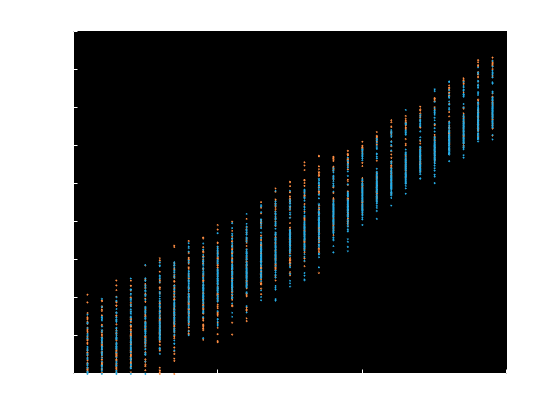

hold off

## Axial Tilt Correction

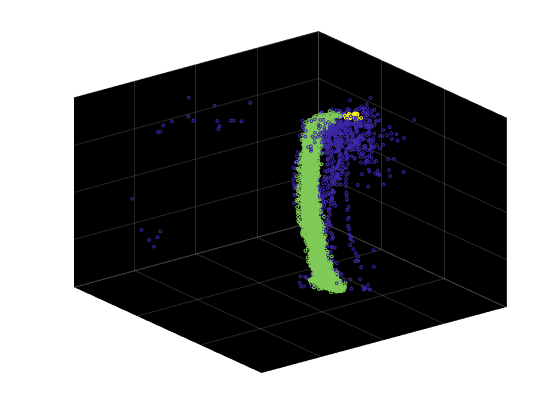

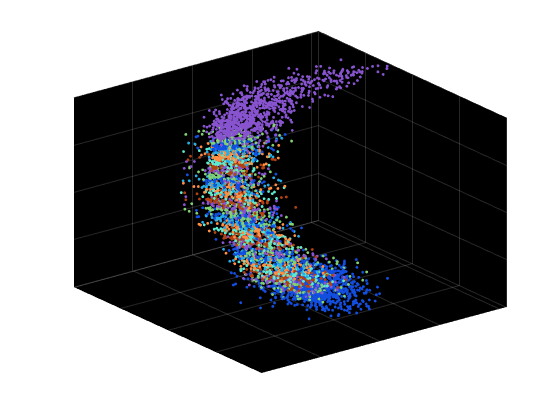

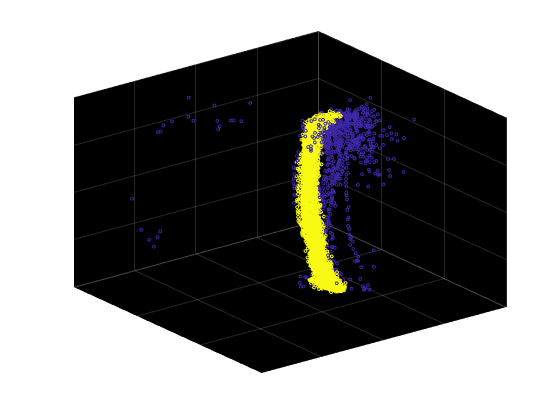

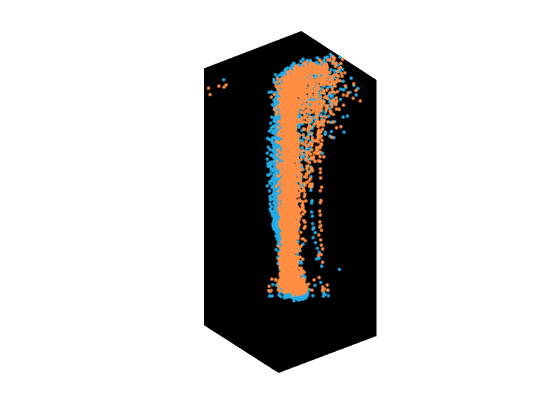

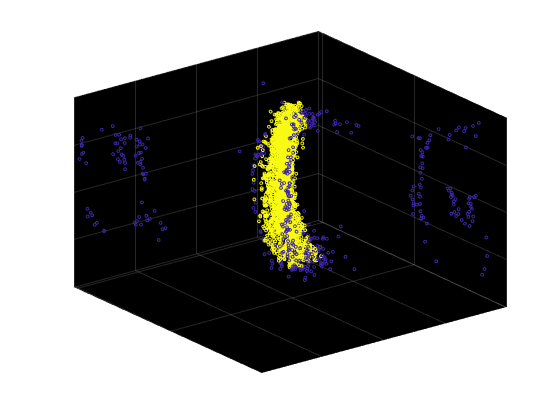

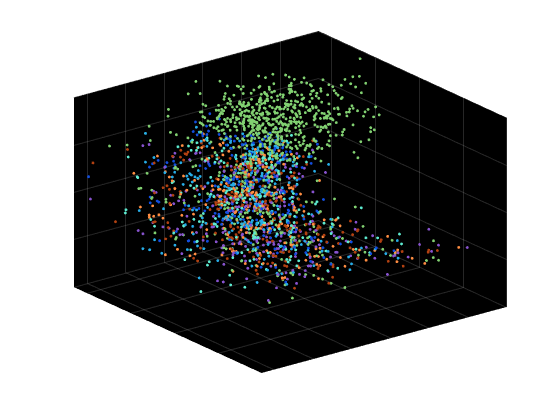

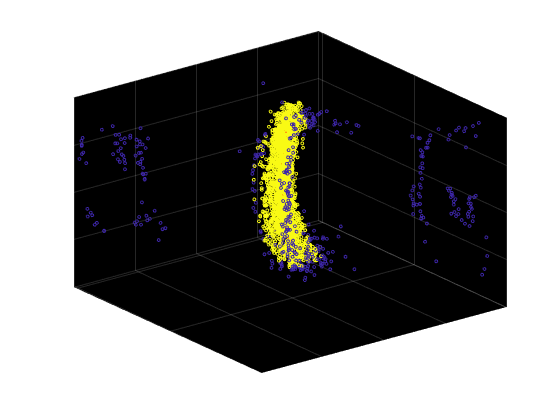

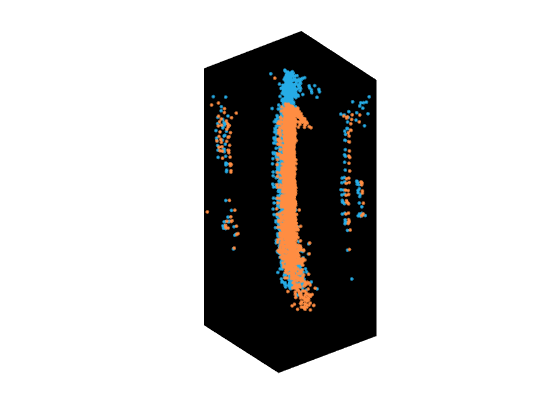

close all;
clearvars average_points
for jj = 1:2
    
    data = [xfs.(colors{jj}),yfs.(colors{jj}),zf.(colors{jj})]; % ZF is normalized by Q
    % Here we use a db scan to determine the 'central column'
    sub_data = data(data(:,3)>-6.6 & data(:,3)<10,:);
    clust = dbscan(sub_data, 0.04/q, 15);
    % Attempt to grab subset of data
%     histogram(clust(clust>-1),1:1:100)
%     sub_data = [xfs.(colors{jj}),yfs.(colors{jj}),zf.(colors{jj})]
    scatter3(sub_data(:,1),sub_data(:,2),sub_data(:,3),5,clust)
    figure
    % The model will be based off of the
    selection_cluster = clust == mode(clust);
    model = sub_data(selection_cluster,:);
    [dz, I] = sort(model(:,3));
    model = model(I,:);
    % Going to attempt a k-means cluster protocol
%     num_pts = 20; % define number of points in final 
%     start_inds = randi(numel(model(:,1)), [num_pts,1]);
%     k_model = model(start_inds,:);
%     for i = 1:200 % Convergence loop
%         k_index = knnsearch(k_model,model);
%         for j = 1:num_pts
%             pts = k_index == j;
%             for k = 1:3
%                 k_model(j,k) = mean(model(pts,k));
%             end
%         end
%     end
%     figure
%     scatter3(model(:,1),model(:,2),model(:,3),5,'filled')
%     hold on
%     scatter3(k_model(:,1),k_model(:,2),k_model(:,3),50,'filled')
%     hold off
%     title('Model')
    splz = min(model(:,3)):0.05/q:max(model(:,3));
    for i = 1:numel(splz)
        ind = abs(model(:,3) - splz(i)) < 0.5/q;
        average_points(i,:) = mean(model(ind,:),1);
        scatter3(model(ind,1),model(ind,2),model(ind,3),5,'filled')
        hold on
    end
    hold off
    title('Segmented Model')
%     for i = 1:3
%         average_points(:,i) = gausssmooth(average_points(:,i),8,20);
%     end
    % Assign axial tilt parameters to z_calibration
%     cal.(colors{jj}).x_tilt = k_model(:,1);
%     cal.(colors{jj}).y_tilt = k_model(:,2);
%     cal.(colors{jj}).z_tilt = k_model(:,3);
    cal.(colors{jj}).x_tilt = average_points(:,1);
    cal.(colors{jj}).y_tilt = average_points(:,2);
    cal.(colors{jj}).z_tilt = average_points(:,3);
%     figure
    if make_graphs == 1
        figure
        scatter3(sub_data(:,1),sub_data(:,2),sub_data(:,3),5,clust == mode(clust))
%         zlim([-10 10])
        hold on
        plot3(average_points(:,1),average_points(:,2),average_points(:,3),'r.')
        title('Look Here')
        figure
%         plot3(xfs.(colors{jj}),yfs.(colors{jj}),zf.(colors{jj}),'.')
        hold off
    end
    [splx, sply] = get_axial_tilt_spline(cal.(colors{jj}),zf.(colors{jj}));
    
    %     plot3(xfs.(colors{jj})-splx,yfs.(colors{jj})-sply,zf.(colors{jj}),'.')
    index = zf_um.(colors{jj}) ~= -5;
    xt = xf.(colors{jj})(index);
    yt = yf.(colors{jj})(index);
    zt = zf_um.(colors{jj})(index)/q;
%     hold off
    ncoords = make_astigmatism_corrections([xt,yt,zt],cal.(colors{jj}),q);
    plot3(ncoords(:,1),ncoords(:,2),ncoords(:,3),'.')
    hold on
    plot3(sub_data(:,1)*q,q*sub_data(:,2),q*sub_data(:,3),'.')
    hold off
    axis equal
    xlim([-0.5 0.5])
    ylim([-0.5 0.5])
    zlim([-10 10]*q)
    title([colors{jj},' channel'])
    figure
end

for jj =1:2
    
    index = zf_um.(colors{jj}) ~= -5;
    xt = xf.(colors{jj})(index);
    yt = yf.(colors{jj})(index);
    zt = zf_um.(colors{jj})(index)/q;
%     hold off
    ncoords = make_astigmatism_corrections([xt,yt,zt],cal.(colors{jj}),q);
    plot3(ncoords(:,1),ncoords(:,2),ncoords(:,3),'.')
    hold on
end
hold off
legend(colors{1}, colors{2})

## Save Data


save('z_calib.mat','cal');